clear
load fisheriris.mat

Once the dataset is loaded, we can start with the steps.

- (At*A)*X=At*b --> solve (LSQ)

- Find MSE both for the train and test subsets

- Plot with manual change of weights to see what shpae does MSE have (should be parabolic)

- Plot different norms (L1, L2, Linfty)

In order to do so, we first need a model to calculate the accuracy of

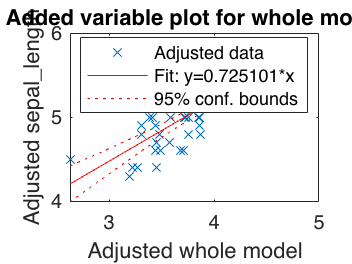

sepal_length = meas(1:50, 1);
sepal_width = meas(1:50, 2);
petal_length = meas(1:50, 3);
tbl = table(sepal_length, sepal_width, petal_length);
mdl = fitlm(tbl,'sepal_length ~ sepal_width+petal_length');
plot(mdl);

**1. Solve equation**

In this equation, *A* is the vector containing the weights, *X* is the Design matrix and *b* stands for the outputs.

The error equation: Y - X*w = 0 is an incompatible system because X doesn't have an inverse. (*Y* is the output, *X* is the deisgn matrix, *w* are the weights). As we cannot solve it, we can only minimize it following one of the norms. With l2;

min x 1/2 (b-AX)^2 = 1/2 (b-AX)t (b-AX) =f(x)

And f'(x) = At (b-AX) = 0 --> (AtA)X = At b

b = mdl.Fitted

b =     5.0365
    4.7028
    4.8079
    4.7979
    5.1032
    5.3885
    4.9697
    4.9981
    4.6360
    4.7979


X = mdl.Variables(:, 2:3)

X = 50×2 table
    sepal_width    petal_length
    ___________    ____________

        3.5            1.4     
          3            1.4     
        3.2            1.3     
        3.1            1.5     
        3.6            1.4     
        3.9            1.7     
        3.4            1.4     
        3.4            1.5     
        2.9            1.4     
        3.1            1.5     
        3.7            1.5     
        3.4            1.6     
          3            1.4     
          3            1.1     
          4            1.2     
        4.4            1.5     


A = mdl.Coefficients(2:3, 2)

A = 2×1 table
                       SE   
                    ________

    sepal_width     0.090356
    petal_length     0.19722


The equation, solved:

A=table2array(A)

A =     0.0904
    0.1972


X=table2array(X)

X =     3.5000    1.4000
    3.0000    1.4000
    3.2000    1.3000
    3.1000    1.5000
    3.6000    1.4000
    3.9000    1.7000
    3.4000    1.4000
    3.4000    1.5000
    2.9000    1.4000
    3.1000    1.5000


left = (A'*A)*X

left =     0.1647    0.0659
    0.1412    0.0659
    0.1506    0.0612
    0.1459    0.0706
    0.1694    0.0659
    0.1835    0.0800
    0.1600    0.0659
    0.1600    0.0706
    0.1365    0.0659
    0.1459    0.0706


**2. Find MSE for test and train subsets**

The MSE or Mean Squared Error measures the accuracy and performance of the output/model. It adds the squared difference between the data point and the predicted point of each of the given data points and then divides it by the total of samples *m* (hence the "mean"). It can be written as: `MSE=1/m*sum(y_predicted-y_real)^2`. See formula (5.2) In the reference book.

Matlab has a built in function to do so; error. Used as `err = error(B,TBLnew,Ynew)`.

testing_X = table2array(mdl.Variables(1:10, :));
testing_Y = mdl.Fitted(1:10);
training_X = table2array(mdl.Variables(11:50, :));
training_Y = mdl.Fitted(11:50);

MSE_test=0;
for i=1:length(testing_Y)
    MSE_test = MSE_test + (abs(testing_Y(i)-testing_X(i, 2:3)*A))^2;
end
MSE_test = 0.5/length(testing_Y)*MSE_test

MSE_test = 9.4275

disp(MSE_test)

    9.4275




MSE_train=0;
for i=1:length(training_Y)
    MSE_train = MSE_train + (abs(training_Y(i)-training_X(i, 2:3)*A))^2;
end
MSE_train = 0.5/length(training_Y)*MSE_train

MSE_train = 9.8169

disp(MSE_train)

    9.8169



Relative error between MSE of the testing and training sets:

Rel_err = abs(MSE_train-MSE_test)/MSE_test*100

Rel_err = 4.1302

**3. Plot with manual change of weights to see what shpae does MSE have (should be parabolic)**

Now, the same formulation for the MSE can be used to explore how different values of the weights affect the mathematical behaviour of such function.

Operating with the first weight (0.0904)

x = linspace(0.05, 0.15, 10);

MSE_train1 = zeros(length(x));
for i=1:length(x)
    A(1) = x(i);
    for j=1:length(training_Y)
        MSE_train1(i) = MSE_train1(i) + (abs(training_Y(j)-training_X(j, 2:3)*A))^2;
    end
    MSE_train1(i) = 0.5/length(training_Y)*MSE_train1(i);
end


plot(x, MSE_train1)

The same can be done with the second weigth:

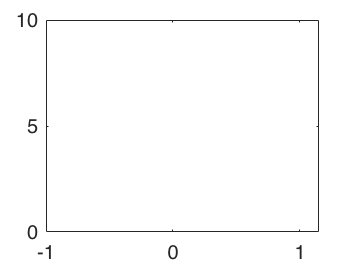

close all
x = linspace(0.15, 0.15, 10);
MSE_train2 = zeros(length(x));
for i=1:length(x)
    A(2) = x(i);
    for j=1:length(training_Y)
        MSE_train2(i) = MSE_train2(i) + (abs(training_Y(j)-training_X(j, 2:3)*A))^2;
    end
    MSE_train2(i) = 0.5/length(training_Y)*MSE_train2(i);
end

plot(x, MSE_train2);

**4. Plot different norms (L1, L2, Linfty)**

We can try different formulations.

- L1 or Manhattan norm simply averages the difference, without sqaring it. This is `L1 = 1/m*(abs(y_predicted-y_real)`

L1_train=0;
for i=1:length(training_Y)
    L1_train = L1_train + (abs(training_Y(i)-training_X(i, 2:3)*A));
end
L1_train = 1/length(training_Y)*L1_train

L1_train = 4.2882

disp(L1_train)

    4.2882



- L infinity norm takes the maximum difference.

Li_train=0;
for i=1:length(training_Y)
    Li_train = Li_train + (abs(training_Y(i)-training_X(i, 2:3)*A));
end
Li_train = 1/length(training_Y)*Li_train

Li_train = 4.2882

disp(Li_train)

    4.2882

